# Práctica 3: Grafos.

Equipo: Miguel Egido Morales y Alfredo Robledano Abasolo

Grupo: 3ºB

El objetivo de esta práctica es programar el algoritmo de Kruskal mediante un código de tipo function. Para ello subdividiremos el problema en problemas más pequeños. Para ello recuerda que el objetivo es encontrar un subgrafo **CONEXO** $S=(V(G),C)$ del grafo $G=(V(G),E(G))$ tal que $C$ fuera un conjunto conectador. Para ello, la idea es ir añadiendo aristas al grafo $G'=(V(G),\{\})$ hasta conseguir la propiedad de finalización del algoritmo de Kruskal cumpliendo el resto de pasos.

Recordemos que un grafo $G=(V(G),E(G))$ se podía dar por su matriz de adyacencia $A=Ad(G)$.

## **Problema 1**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y un vértice $v=\{i,j\}\in E(G)$ (el cual se puede representar por la entrada $(i,j)=(j,i)$ de la matriz $A$) y sus outputs sean un array de carácteres especificando si dicha arista pertenecía a un ciclo (no trivial) o no. Nótese que si no existe dicha arista debe dar el mensaje de error correspondiente y que si $A=Ad(G)$ no es una matriz correspondiente a una de adyancencia debe dar error también.

### Respuesta 1

En la última sección de este documento se define y detalla el funcionamiento de la función perteneceCiclo(), función que permite comprobar si una arista de un grafo pertenece a un ciclo. A continuación se presenta un ejemplo de uso:

clear, clc, clf

A = [
    0, 1, 0, 0, 1;
    1, 0, 1, 0, 0;
    0, 1, 0, 1, 1;
    0, 0, 1, 0, 0;
    1, 0, 1, 0, 0;
];

Grafo G:

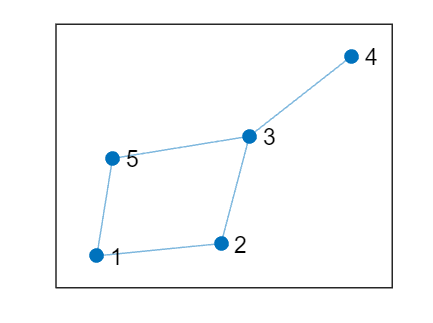

G = graph(A);
figure
plot(G)


arista = [3, 5];

res = perteneceCiclo(A, arista);
disp(res);

   1



## **Problema 2**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y sus outputs sean un array de carácteres indicando si el grafo es conexo o no.

### Respuesta 2

En la última sección de este documento se define y detalla el funcionamiento de la función esConexo(), función que permite comprobar si un grafo es conexo. A continuación se presentan dos ejemplos de uso:

clear, clc, clf
% Ejemplo conexo
A = [
    0 1 1 0 0 0 0 0 0 1;
    1 0 1 0 1 0 0 0 0 0;
    1 1 0 1 0 0 0 0 0 0;
    0 0 1 0 1 1 0 0 0 0;
    0 1 0 1 0 0 1 0 0 0;
    0 0 0 1 0 0 1 0 0 0;
    0 0 0 0 1 1 0 1 0 0;
    0 0 0 0 0 0 1 0 1 0;
    0 0 0 0 0 0 0 1 0 1;
    1 0 0 0 0 0 0 0 1 0;
];

Grafo G:

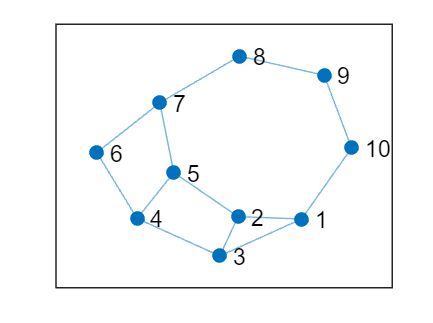

G = graph(A);
figure
plot(G)


resultado = esConexo(A);
disp(resultado);

   1




% ejemplo no conexo
B = [
    0 1 0 0 1 0 0 0 0 0;
    1 0 1 0 0 0 0 0 0 0;
    0 1 0 1 0 0 0 0 0 0;
    0 0 1 0 1 0 0 0 0 0;
    1 0 0 1 0 0 0 0 0 0;
    0 0 0 0 0 0 1 0 0 0;
    0 0 0 0 0 1 0 1 0 0;
    0 0 0 0 0 0 1 0 1 0;
    0 0 0 0 0 0 0 1 0 1;
    0 0 0 0 0 0 0 0 1 0;
];

Grafo P:

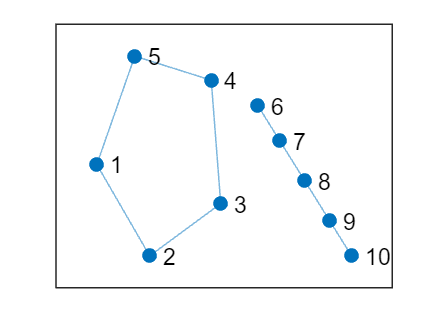

P = graph(B);
figure
plot(P)


res = esConexo(B);
disp(res);

   0



## **Problema 3**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y la matriz $\Omega(G)$ de pesos de $G$ y sus outputs sean o bien la matriz de adyacencia de $S=(V(G),C)$ o bien una matriz $1\times 2$ donde $a_{11}$ sea una matriz $1\times n$ cuyos elementos son números y $n$ el número de vértices a calcular y $a_{12}$ se una matriz $1\times m$ cuyos elementos son matrices $1\times 2$ representando los vértices. (Podéis elegir la opción que prefiaráis).

Pista: Crea una matriz $1\times k$ cuyos elementos sean las aristas de $G$ ordenadas por peso. Nótese que los elementos de esta matriz son matrices $1\times 2$.

### Respuesta 3

En la última sección de este documento se define y detalla el funcionamiento de la función kruskal(), función que permite obtener uno de los posibles árboles de expansión mínima para un grafo dado. A continuación se presenta un ejemplo de uso:

% Matriz de pesos
W = [
    0, 1, 0, 0, 1;
    1, 0, 2, 0, 1;
    0, 2, 0, 2, 3;
    0, 0, 2, 0, 4;
    1, 1, 3, 4, 0;
];

% Matriz de adyacencia
A = logical(W);

Grafo inicial G:

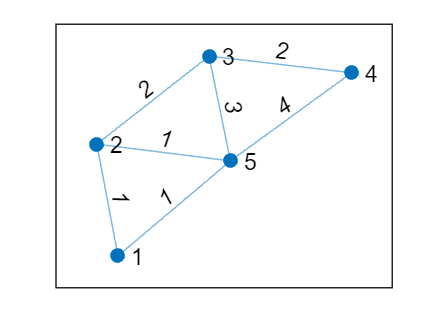

G = graph(W);
figure
plot(G, EdgeLabel=G.Edges.Weight)

Árbol de expansión mínima final S:

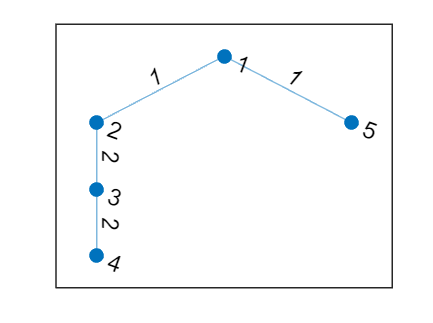

S = kruskal(A, W);
GS = graph(S);
figure
plot(GS, EdgeLabel=GS.Edges.Weight)

## Funciones

#### perteneceCiclo

La función perteneceCiclo() permite comprobar si una arista pertenece a un ciclo. Recibe como entradas la matriz de adyacencia y la arista que se quieren estudiar. Como salida devuelve un valor booleano que indica la pertenecia o no a un ciclo. El método utilizado es el algoritmo de búsqueda por profundidad. Se inicia la exploración desde un extremo de la arista (arbitrariamente primera componente) hasta que encuentre el otro extremo (segunda componente). En caso de no encontrarlo diremos que no pertenece y en caso afirmativo que si pertenece.

function res = perteneceCiclo(A, arista)
    % Dimensiones matriz de adyacencia
    [fil, col] = size(A);
    num_nodos = fil;
    % Matriz de adyacencia debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(A, A')) % Simétrica
        error('Error: Matriz de adyacencia no válida');
    end

    % La arista debe tener:
    if ~(length(arista) == 2 ... % Dos componentes
        && all(arista == round(arista)) ... % Valores enteros
        && arista(1) ~= arista(2) ... % No ciclos propios
        && all(arista >= 1 & arista <= num_nodos)) % Valores entre 1 y nº de aristas
        error('Error: Arista no válida');
    end

    % Si se puede ir de uno de sus extremos al otro tras eliminarla del grafo inicial
    % Entonces la arista pertenece a un ciclo 
    [res, ~] = dfs(A, arista(1), arista(2));
end

#### esConexo

La función esConexo() permite comprobar si un ciclo es conexo. Recibe como entrada la matriz de adyacencia del grafo que se quiere estudiar. Como salida devuelve un valor booleano que indica la conectividad o no del grafo. El método utilizado es el algoritmo de búsqueda por profundidad. Se inicia la exploración arbitrariamente desde el primer nodo (actual=1) y si no es capaz de visitar todos los nodos entonces diremos que no es conexo.

function res = esConexo(A)
% Esta funcion comprueba si e grafo es conexo o no
    [fil, col] = size(A);
    % Matriz de adyacencia debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(A, A')) % Simétrica
        error('Error: Matriz de adyacencia no válida');
    end
    
    % De manera arbitraria elegimos el primer nodo para comenzar a explorar
    actual = 1;

    % Exploramos todo el grafo (no hay objetivo, que equivale a objetivo=0)
    objetivo = 0;
    
    % Exploración
    [~, visitados] = dfs(A, actual, objetivo);
    
    % Si desde cualquier nodo alcanzamos el resto, el grafo es conexo
    res = all(visitados);
end

#### dfs

La función dfs() permite explorar un grafo. Recibe como entradas la matriz de adyacencia del grafo que se quiere estudiar, el punto desde el que empezar la exploración, objetivo que sirve para detener la exploración al encontrarlo y opcionalmente el vector que guarda la información de que nodos ya han sido visitados . Como salida devuelve por un lado, un valor booleano que indica si el nodo objetivo pertenece a la misma componente conexa que el nodo actual y por otro lado los nodos que han sido visitados. El algoritmo en el que se basa es el deep first search, consiste en observar cuales son los vecinos al nodo actual e ir eliminando aristas según se va avanzando dentro del grafo.

Notas: 

- Si no se especifica el número de visitados se toma como que se han visitado cero nodos.

- Si el objetivo toma valor 0 significa que se explora toda la componente conexa.

- Por simplicidad no se validan variables de entrada (se espera que el resto de funciones que llaman a esta introduzcan inputs adecuados).

function [pertenece_comp_conexa, visitados] = dfs(grafo, actual, objetivo, visitados)
    % Por defecto no se ha visitado ningún nodo
    % (En el caso de no especificar la variable "visitados")
    if nargin < 4
        % Se especifica el vector de nodos visitados
        num_nodos = size(grafo, 1);
        visitados = zeros(1, num_nodos);
    end

    % En cada llamada recursiva el nodo actual se visita
    visitados(actual) = 1;

    % Vecinos al nodo actual
    vecinos = grafo(actual, :);

    % A los nodos vecinos les restamos a los vecinos los que ya hemos visitado
    vecinos_no_visitados = find(vecinos - (vecinos & visitados));

    %% Si se quiere dibujar
    % figure
    % plot(graph(grafo))

    % Si el objetivo toma valor 0 (No hay objetivo)
    % Se recorre toda la componente conexa del nodo actual
    if ~objetivo

        % Si no hay objetivo no hablamos de pertenecer a la componente
        pertenece_comp_conexa = -1;

        for i = 1:length(vecinos_no_visitados)
            % Eliminamos la arista que hemos utilizado para visitar
            arista = [actual, vecinos_no_visitados(i)];
            grafo(arista, flip(arista)) = 0;
    
            % Por recursión se siguen visitando
            [~, visitados] = dfs(grafo, vecinos_no_visitados(i), objetivo, visitados);
        end

    % Si existe objetivo el algoritmo se detiene al encontrarlo
    else

        % Inicialmente suponemos que el objetivo no pertenece
        pertenece_comp_conexa = false;

        for i = 1:length(vecinos_no_visitados)
            % Finaliza la recursión si hemos visitado al objetivo
            if ismember(objetivo, find(visitados))
                pertenece_comp_conexa = true;
                break
            end
    
            % Eliminamos la arista que hemos utilizado para visitar
            arista = [actual, vecinos_no_visitados(i)];
            grafo(arista, flip(arista)) = 0;
    
            % Por recursión se siguen visitando
            [pertenece_comp_conexa, visitados] = dfs(grafo, vecinos_no_visitados(i), objetivo, visitados);
            
            % Finalizamos la exploración si se encuentra el objetivo
            if pertenece_comp_conexa
                break
            end
        end
    end
end

#### kruskal

La función kruskal() permite convertir un grafo en un árbol de expansión mínima. Recibe como entradas la matriz de adyacencia del grafo que se quiere estudiar y su matriz de pesos (algo redundante en enunciado dado que un grafo ponderado ya especifica los pesos en su matriz de adyacencia). Como salida devuelve uno de los posibles árboles de expansión mínima. El algoritmo utilizado es el Kruskal y se basa en ir añadiendo aristas según su peso de manera creciente y evitando ciclos que puedan formarse (se busca obtener un árbol).

function S = kruskal(A, W)
    [fil, col] = size(A);
    % Matriz de adyacencia debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(A, A')) % Simétrica
        error('Error: Matriz de adyacencia no válida');
    end

    [fil, col] = size(W);
    % Matriz de pesos debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(W, W')) % Simétrica
        error('Error: Matriz de pesos no válida');
    end

    % Inicializamos un grafo S vacío (su matriz de adyacencia)
    num_nodos = fil;
    S = zeros(num_nodos);

    % Obtenemos los pesos posibles ordenados
    pesos = unique(W(W~=0));
    pesos = sort(pesos);

    % Por ser la matriz simétrica solo necesito trabajar con la mitad
    aux = triu(W);
    for i = 1:length(pesos)
        % Obtenemos las aristas para el peso(i)
        [fil, col] = find(aux == pesos(i));
        aristas = [fil, col];

        % Trataremos de añadir cada arista evitando ciclos
        for j = 1:size(aristas, 1)
            arista = aristas(j, :);
            
            % Se irán añadiendo aristas a S hasta que el grafo sea conexo
            S(arista(1), arista(2)) = pesos(i);
            S(arista(2), arista(1)) = pesos(i);

            % Si el grafo es conexo hemos terminado
            if esConexo(S)
                return
            end

            % Si al añadir una arista se crea un ciclo la eliminamos
            if perteneceCiclo(S, arista)
                S(arista(1), arista(2)) = 0;
                S(arista(2), arista(1)) = 0;
            end
        end
    end
end